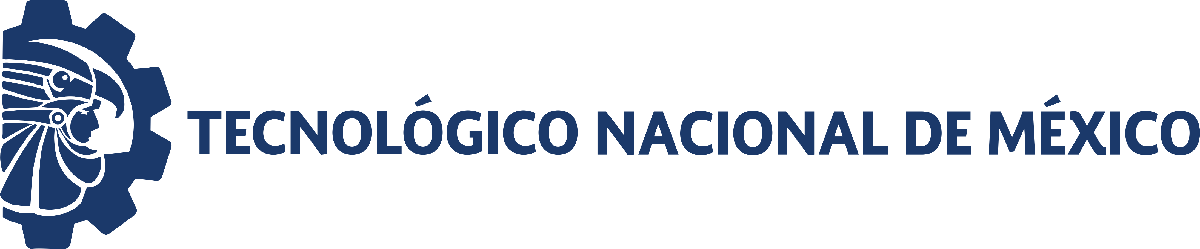                                 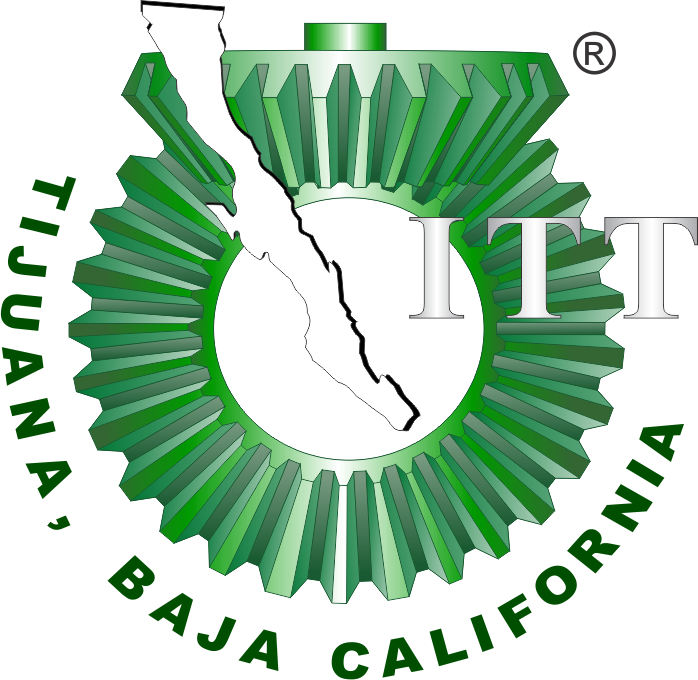

# Práctica 1: Diseño de contoladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

##            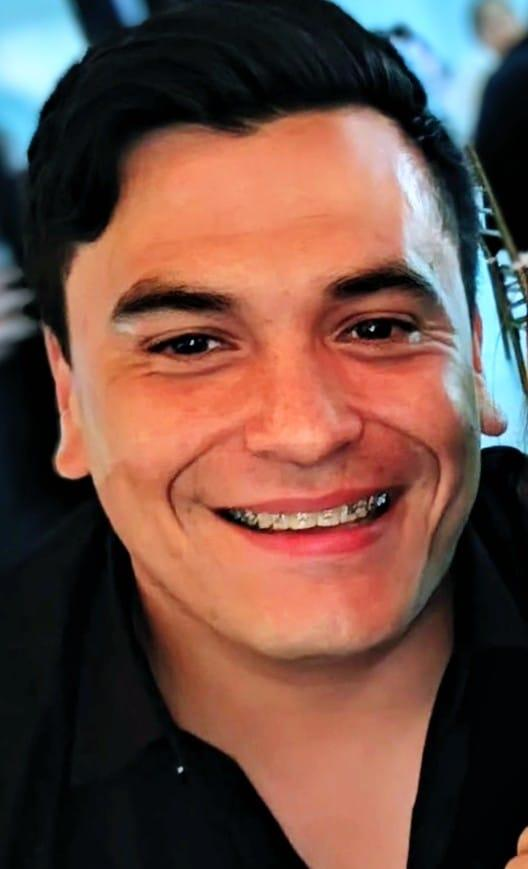

Nombre del alumno: Alan Omar Garcia Toledo

Número de control: 20210787

Correo institucional: alan.garciat201**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;

parameters.Solver = 'ode15s';
parameters.MaxStep ='1E-3';
set_param('Sistema/Vs0(t)','VectorFormat','1-D array')


## Respuesta al escalón

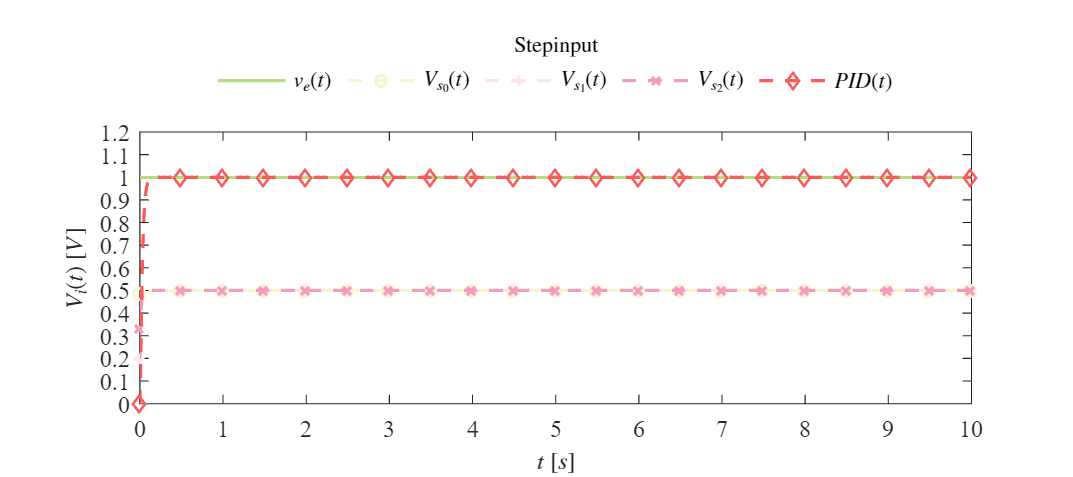

Signal = 'Step';
set_param('Sistema/S1','sw','1');
set_param('Sistema/Ve(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs0,x1.Vs1,x1.Vs2,x1.PID,Signal)

## Respuesta al impulso

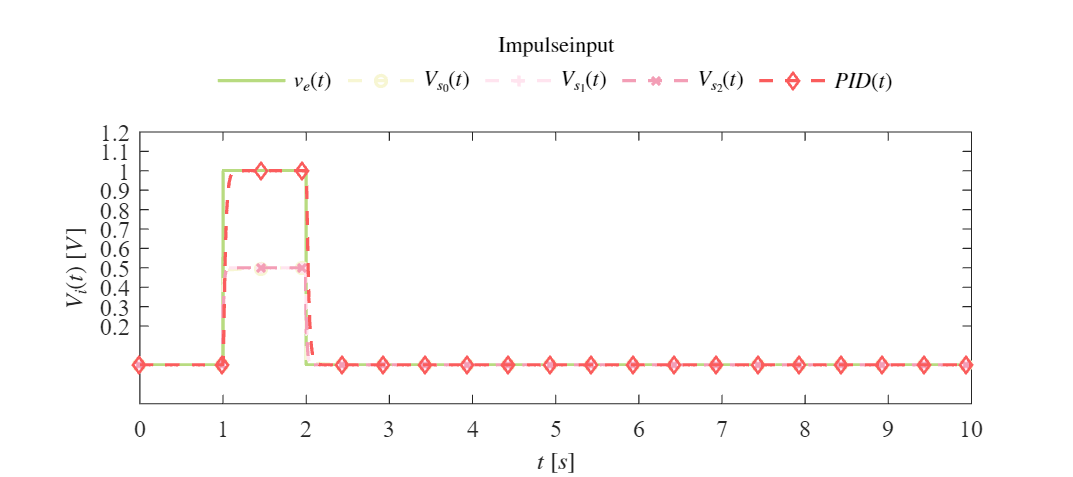

Signal = 'Impulse';
set_param('Sistema/S1','sw','0');
set_param('Sistema/Ve(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs0,x2.Vs1,x2.Vs2,x2.PID,Signal)

## Respuesta a la rampa

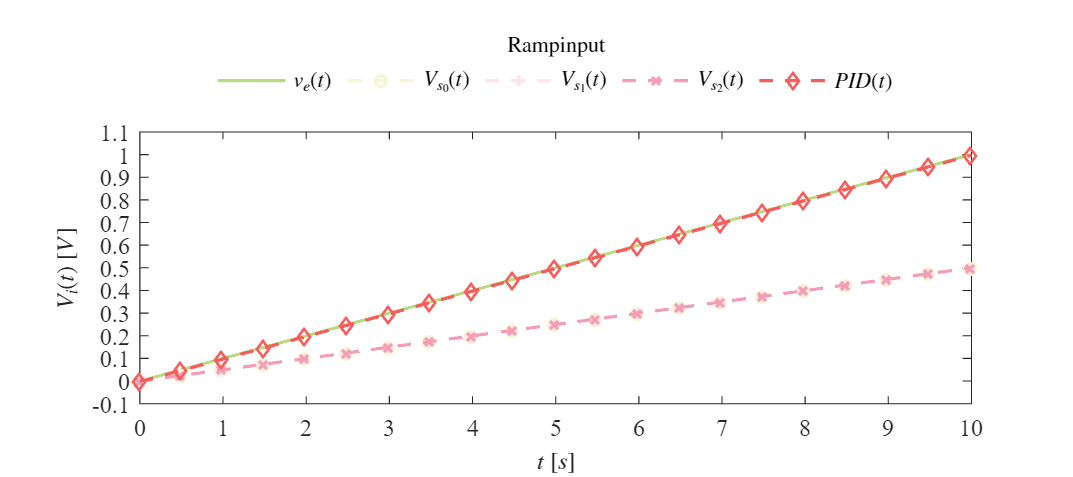

Signal = 'Ramp';
set_param('Sistema/S2','sw','1');
set_param('Sistema/Ve(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs0,x3.Vs1,x3.Vs2,x3.PID,Signal)

## Respuesta a la función sinusoidal

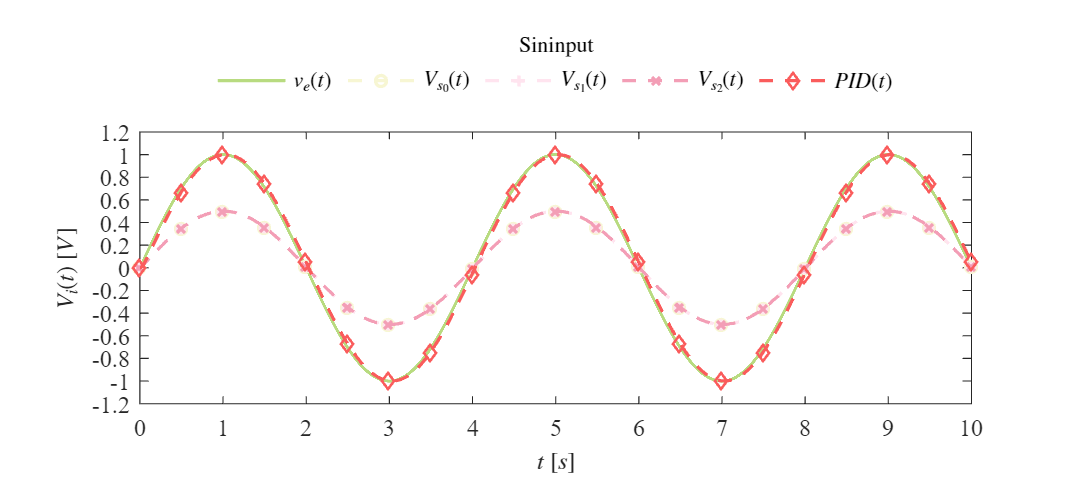

Signal = 'Sin';
set_param('Sistema/S2','sw','0');
set_param('Sistema/Ve(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs0,x4.Vs1,x4.Vs2,x4.PID,Signal)

## Funcion. Respuesta a las señales

function plotsignals(t,Pao,P0,P1,P2,PID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    


   colorgraficas = [184, 219, 128;
                247, 246, 211;
                255, 228, 239;
                243, 158, 182;
                250, 92, 92] / 255;
    colororder(colorgraficas)



    plot(t,Pao,'-',t,P0,'--o',t,P1,'--+',t,P2,'--x',t,PID,'--d', ...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L=legend('$v_e(t)$','$V_{s_0}(t)$','$V_{s_1}(t)$','$V_{s_2}(t)$','$PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'location',...
        'NorthOutside','box','off','Orientation','Horizontal')
    title(L,[Signal,'input'],'FontSize',10)
    
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    if Signal =="Step"
        xlim([0,10]); xticks(0:1:10);
        ylim([0,1.2]); yticks(0:0.1:1.2)



elseif Signal =="Impulse"
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.2,1.2]); yticks(0.2:0.1:1.2)
elseif Signal=="Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1);
elseif Signal=="Sin"
        ylim([-1.2,1.2]); yticks(-1.2:0.2:2);
end     
   exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
%exportgraphics(gcf,[Signal,'.png'],'ContentType',600);
%print(Signal,'-dsvg', 'r600');
%print(Signal, 'depsc','-r600');
end